## Question 1

Maximum-likelihood estimate and maximum-a-posteriori estimate

setting various constants,

rng(0);

Ns = [5 10 20 40 60 80 100 500 1000 10000];

% parameters of true distribution
muTrue = 10;
sigmaTrue = 4;

% parameters of gaussian prior
muPrior = 10.5;
sigmaPrior = 1;

% parameters of uniform prior
aUniform = 9.5;
bUniform = 11.5;

% number of times to repeat the experiment
M = 100;

to store errors of MLE and MAP

MLE_error = zeros(10, M);
MAP1_error = zeros(10, M);
MAP2_error = zeros(10, M);

As derived in the report of this question,


$$\hat{\mu}^{ML} = \bar{x} = \frac{\sum x_{i}}{N} = \text{ Sample Mean}$$



$$\hat{\mu}^{MAP1} = \frac{\bar{x}\sigma_{\text{prior}}^{2} + \mu_{\text{prior}}\sigma_{\text{true}}^{2}/N}{\sigma_{\text{prior}}^{2} + \sigma_{\text{true}}^{2}/N }$$



$$\hat{\mu}^{MAP2} = 
    \begin{cases}
        \bar{x} & \text{ if } \: a \leq \bar{x} \leq b \\
        a & \text{ if } \: \bar{x} < a \\
        b & \text{ if } \: b < \bar{x}
    \end{cases}$$


for i=1:1:10
    N = Ns(i); % value of N

    % generating samples from true distribution
    samples = randn(N, M).*sigmaTrue + muTrue;
    
    % calculating their sample mean
    sampleMean = sum(samples)/N;
    
    % getting MAP estimates by using formulas written above
    MAP1 = (sampleMean.*sigmaPrior.*sigmaPrior + muPrior.*sigmaTrue.*sigmaTrue./N)./(sigmaPrior*sigmaPrior + sigmaTrue*sigmaTrue/N);
    MAP2 = min(max(sampleMean, aUniform), bUniform);
    
    % calculating relative erros and storing them
    MLE_error(i,:) = abs(sampleMean - muTrue)./muTrue;
    MAP1_error(i,:) = abs(MAP1 - muTrue)./muTrue;
    MAP2_error(i,:) = abs(MAP2 - muTrue)./muTrue;
end

Plotting of relative errors in estimates,

figure;
boxplot(MLE_error.','Colors','r','Labels',Ns,'Widths',0.2,'Positions',(1:numel(Ns)))

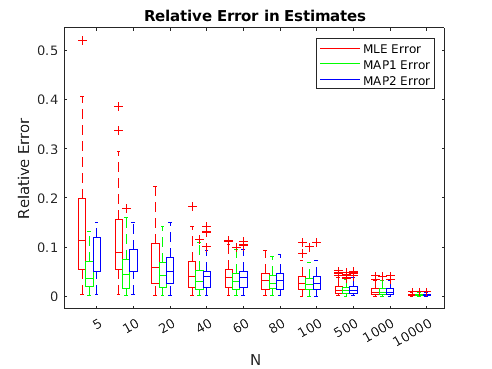

hold on;
boxplot(MAP1_error.','Colors','g','Labels',Ns,'Widths',0.2,'Positions',(1:numel(Ns))+0.2)
hold on;
boxplot(MAP2_error.','Colors','b','Labels',Ns,'Widths',0.2,'Positions',(1:numel(Ns))+0.4)
xlabel("N")
ylabel("Relative Error")
title("Relative Error in Estimates")
plot(NaN,1,'Color','r')
plot(NaN,1,'Color','g')
plot(NaN,1,'Color','b')
legend({'MLE Error','MAP1 Error','MAP2 Error'})